load('ultrasound_data_set-1.mat');



figure
%plot echo signal
plot(time.*10^6, RF(:,128));
xlabel('Time (\mus)')
ylabel('Voltage (V)');
%choose dynamic range
dr = -60

dr = -60

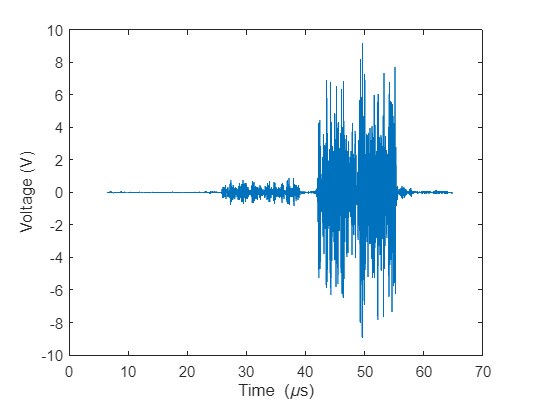

%get envelope of signal
analytic_signal = hilbert(RF);
ultrasound_envelope = sqrt(real(analytic_signal).^2 + imag(analytic_signal).^2);

%logarithmic compression
%log_compression = 20*log10(ultrasound_envelope);

%Test without log compression
log_compression = ultrasound_envelope;

%normalization
normalization = log_compression - max(log_compression, [], "all");


distance = time.*sound_speed/2*10^3;
BM = normalization;
BM(BM < dr) = NaN;
width = -15:image_width*10^2/256:15;

%Image
colormap('gray');

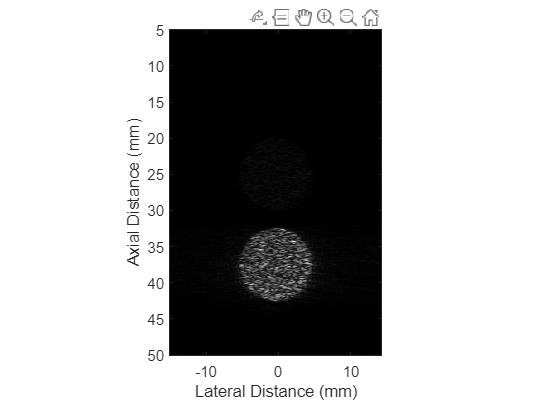

BmodeImage = imagesc(width, distance, BM);
xlabel('Lateral Distance (mm)');
ylabel('Axial Distance (mm)');
axis image;

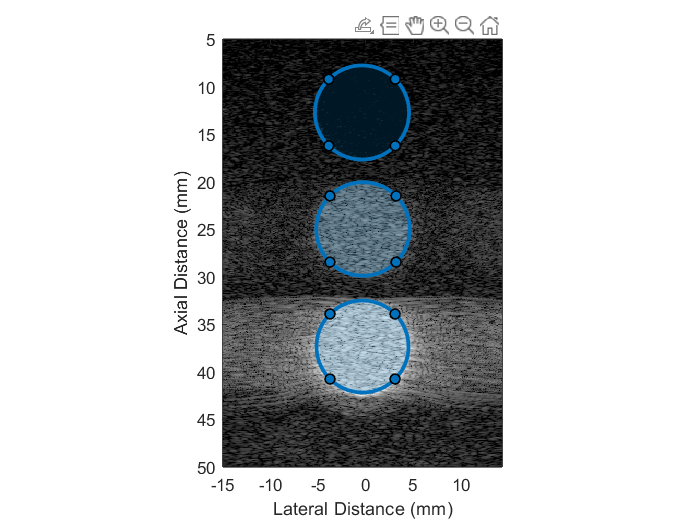



%Lesions
lesions = struct;
masks = struct;
signals = struct;
%Logic matrix to hold masks for all three lesions
total_lesions = false(size(BM));

for i = 1:3
    %Draw ROI for each lesion
    lesions(i).lesion = drawcircle;
    %Create a binary mask
    masks(i).mask = createMask(lesions(i).lesion);
    %Get legion signals from the mask
    signals(i).signal = BM(masks(i).mask);
    %Make any NaN entries be 0
    signals(i).signal(isnan(signals(i).signal)) = 0;
    %Logical matrix that has masks for all three lesions
    total_lesions = total_lesions | masks(i).mask;
end


%Get background by getting values that are not in the total_lesions mask
background_signals = BM(~total_lesions);
%Set any NaN values to 0
background_signals(isnan(background_signals)) = 0;
%Contrast to Noise Ratio Calculations
for i = 1:3
CNR(i) = abs(mean(signals(i).signal) - mean(background_signals))/sqrt((std(signals(i).signal)^2 + std(background_signals)^2)/2);
end

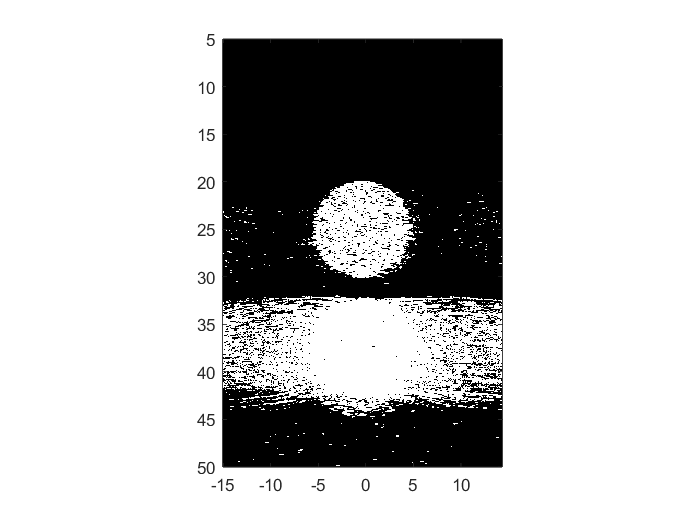

%Machine Learning
scaled_image = rescale(BM);
gray_thresh = graythresh(scaled_image);
binary_image = imbinarize(scaled_image, gray_thresh);
imagesc(width, distance, binary_image);
axis image;